# PSET 4

# Tarun Kamath

## Problem 1: Analyzing spike trains and tuning curves from neurons in the primary visual cortex

- So we will have to squeeze our data and then transpose it before graphing the data using the rasterPlot function given to us:

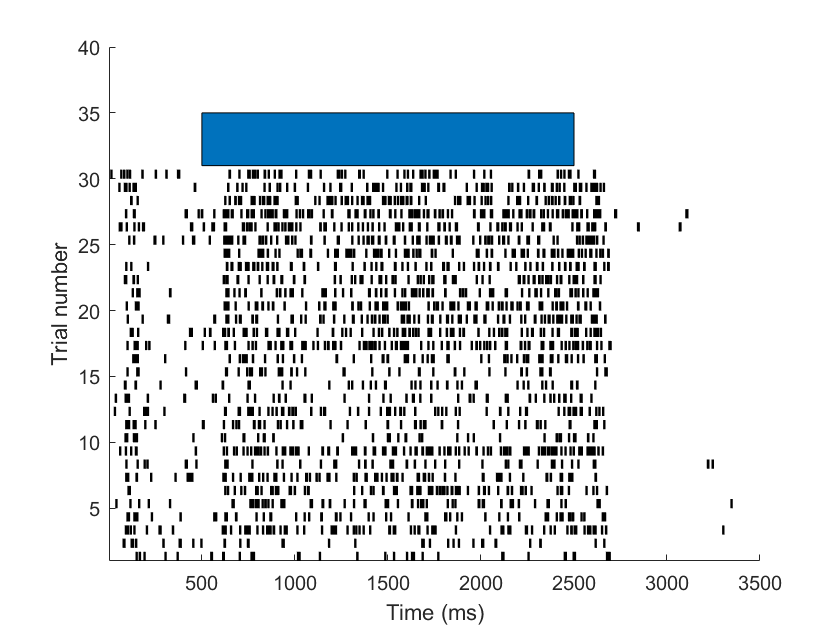

load('dataSur.mat'); %load the data
data = squeeze(spikes(6,:,:)); %take only the orientation #6 data 
data2 = data'; 
rasterPlot(data2, 1, 500, 2500); %produce a raster plot
xlabel('Time (ms)');
ylabel('Trial number');

It seems as though our neuron **does** respond to this stimulus orientation. We observe a notable increase in firing rate when the stimulus is turned on (represented by the blue bar) and a drop off in firing rate afterwards. 

2. Now we have to make a corresponding bar graph for this stimulus #6. We note that before attempting this that the stimulus is given in terms of ms but we are trying to reach the units of Hz (1/s). However, we are also looking at 10 ms bins, thus when converting from ms --> s, we can divide by (10/1000) = 1/100 = 0.01

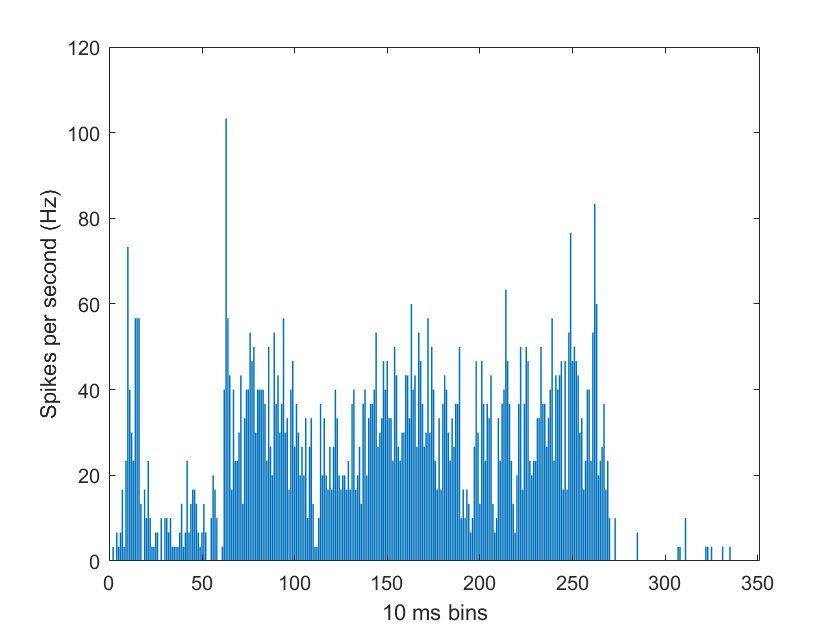

[trials,time] = size(data2);
firingrate = [];
intervals = time/10; %create bins of 10 ms
simplifiedmatrix = mean(data2); %take the average across all trials
for i = 1:intervals %going through 10 ms bins
    beginningnumber = ((i-1)*10)+1; 
    finishingnumber = (10*i);
    intervals(1,i) = (sum(simplifiedmatrix(1,beginningnumber:finishingnumber)))/(0.01); 
                                                   % take the sum across 10 ms, 
                                                   % divide by .01 for 
                                                   % the above stated reason
end
bar(intervals);
xlabel('10 ms bins');
ylabel('Spikes per second (Hz)');

3. So now we will convolve our spike train with a boxcar kernel. 

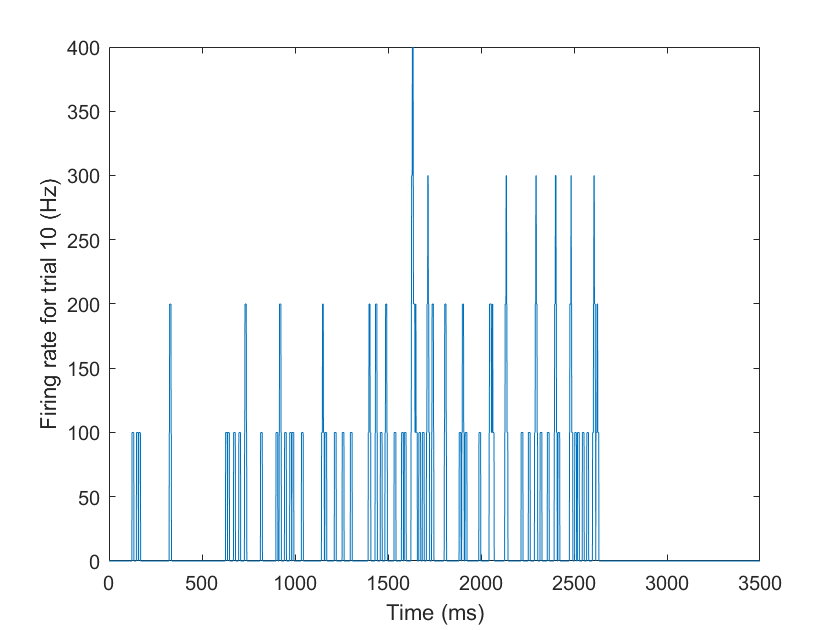


spiketrain = data2(10,:)/.001; %take the data and change it to firing per second
boxcarkernel = ones(1,10)/10; %create a boxcarkernel of width 10 ms
convolution = conv(spiketrain, boxcarkernel, 'same'); %convolve spike train and kernel
plot(convolution);
xlabel('Time (ms)');
ylabel('Firing rate for trial 10 (Hz)');

This somewhat resembles our PSTH that we have above. It is different in that we consider the instantaneous firing rate rather than averaging over 10 ms bins, thus the curve is less smooth. Furthermore, despite smoothing this with our boxcar kernel, there is still significant variations happening over a relatively small timescale since the boxcar kernel itself is only 10 ms. Finally, the shape of this curve does not exactly look like the shape of the PSTH curve since this is only looking at one trial (trial 10) rather than averaging over 30 trials.

4. We show how to make the tuning curve below:

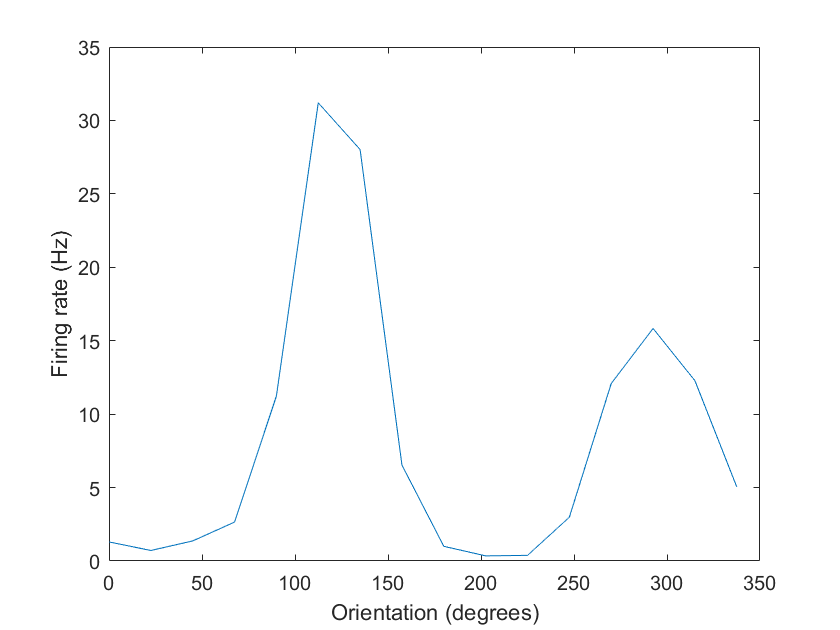

grating = 0:22.5:337.5; %all possible orientations
spikeaverage = [];
for i = 1:18 %18 possible orientations
   array = squeeze(spikes(i,:,:)); %look at each orientation
   array2 = array';
   average = mean(array2); %take average stimulation across trials
   totalspikes = sum(average(1,500:2500)); %take the average while stimulus occurs
   spikeaverage(1,i) = totalspikes/2; %Spikes per second
end
plot(grating,spikeaverage(1,1:16)); %only plot the first 16, last 2 are blanks
xlabel('Orientation (degrees)');
ylabel('Firing rate (Hz)');

5. It seems as though the cell is most responsive to an orientation of 112.5 degrees. The second peak is exactly 180 degrees opposite from that (at 292.5 degrees) and thus shows an increased firing rate since, say, a bar of light that is at 112.5 degrees is also at 292.5 degrees if viewed from the flipped reference frame.

6. We can find the average firing rate to blank stimulus below:

nonspecificspikeaverage = [];
for j = 17:18
    nonspecificarray = squeeze(spikes(j,:,:)); %looking at blanks separately
    nonspecificarray2 = nonspecificarray';
    averagenonspecific = mean(nonspecificarray2); %average across trials
    totalnonspecificspikes = sum(averagenonspecific(1,500:2500)); %similar set up to 1.4
    nonspecificspikeaverage(1,(i-16)) = totalnonspecificspikes/2; %similar set up to 1.4
end

From this we find that the average firing rate of the cell for stimulus 17 is 3.15 and for stimulus 18 it is 3.2 (both in Hz). Thus the average firing rate of the cell to a blank stimulus is **3.175 Hz.**

7. We can replot the firing rate below:

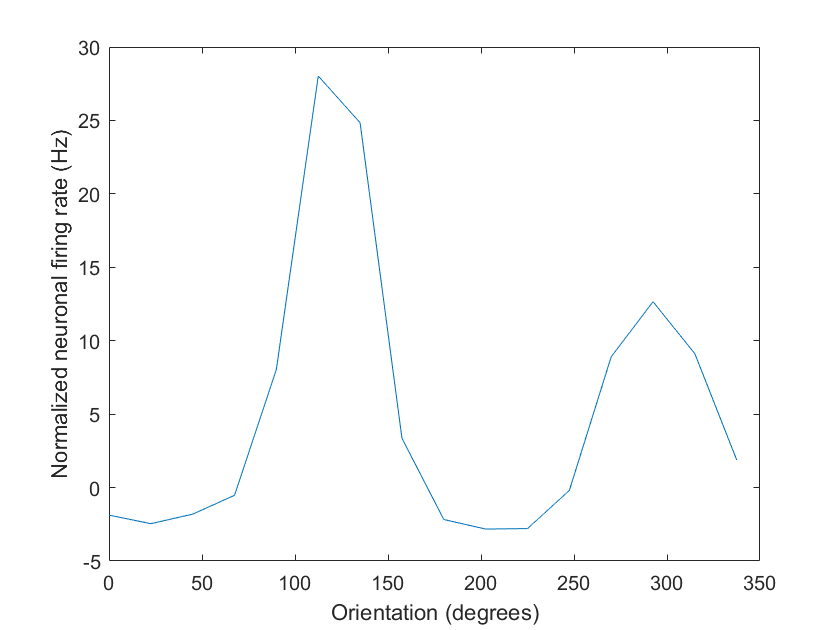

normalizedspikeaverage = spikeaverage - 3.175; %subtractthe baseline firing
plot(grating, normalizedspikeaverage(1,1:16)); 
xlabel('Orientation (degrees)');
ylabel('Normalized neuronal firing rate (Hz)');

The firing rate can go negative when the firing rate of the neuron in response to the stimulus orientation is actually **less **than the unstimulated neuronal firing rate. This would mean that the neuron is **inhibited **by a stimulus in that particular orientation.

## Problem 2: Estimation of spectro-temporal receptive fields (STRF) with spike-triggered averaging (STA)

- This kernel is separable. We see that there are 4 regions, and if we have a function which on the time domain goes from positive to negative, then we simply need to multiply this by a function which inverts this at this at a value of around 50 ms before spike, thus a function that goes from positive to negative. Thus, this field can be written as the product of two functions and thus is separable.

2. So we will do an element wise multiplication - this should give us a 1x1000000 vector corresponding to the neuronal excitatory drive which we can then plot.

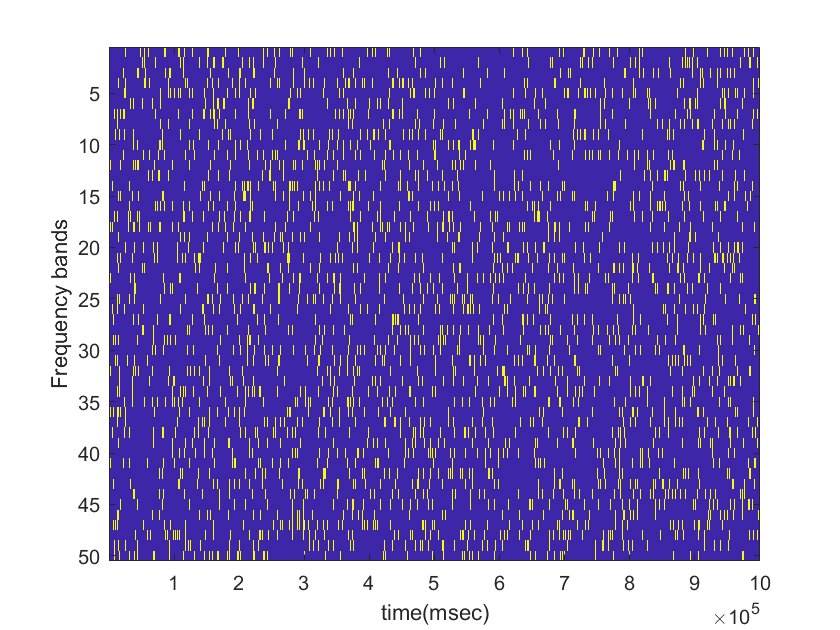

generateStimulus;

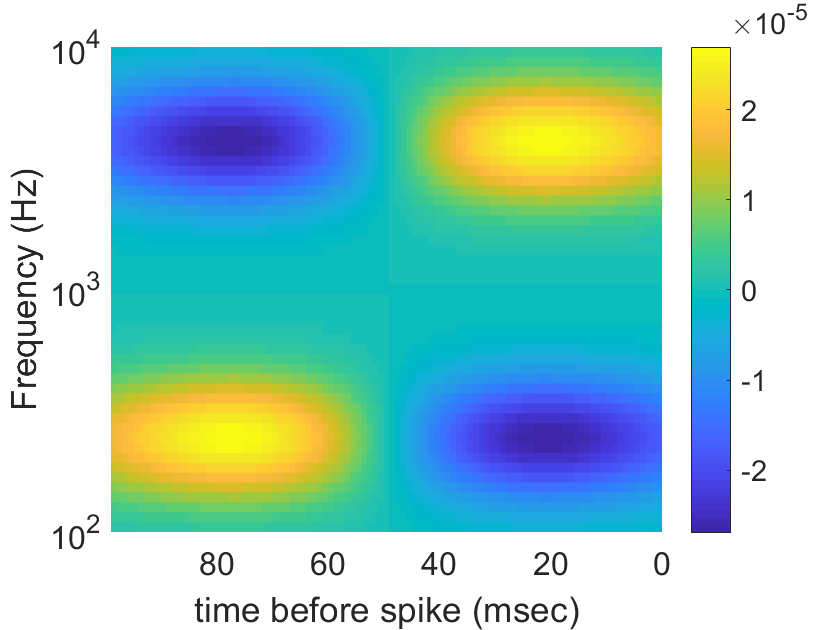

generateKernel;

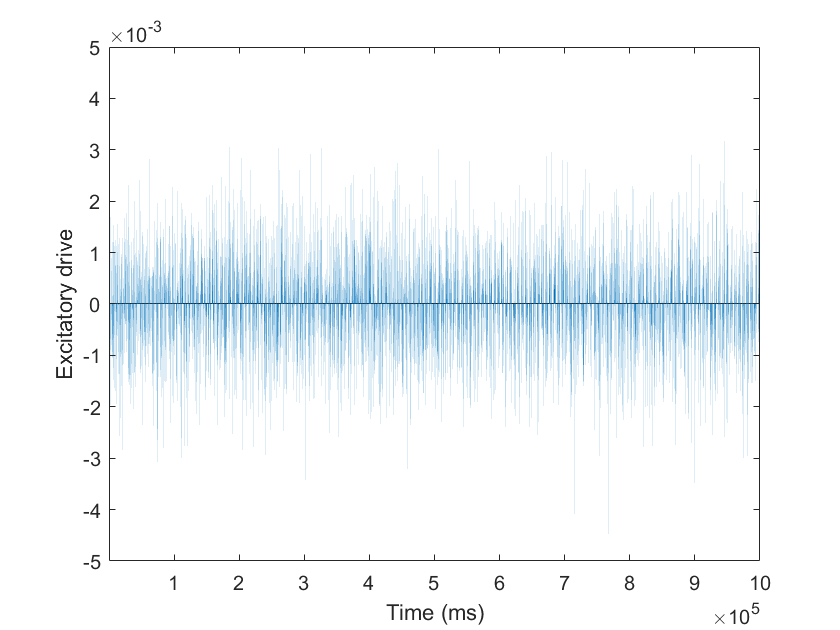

excitdrive = [];
for i = 1:1000000
    if (i+100)>1000000 %during the last part of stimulus, 
                       % when the kernel extends beyond the stimulus
        upperbound = 1000000; %set the end of the stimulus to 1000000
        newStimulus = Stimulus(:,i:upperbound); %create a sub-array stimulus to multiply
        kernelbound = (1000000)-(i-1); 
        newKernel = Kernel(:,1:kernelbound);%create a sub-array kernel to multiply,
                                            % consisting of only the first part of the kernel
        drive = newKernel .* newStimulus;   %element-by-element multiplication
    else
        upperbound = i+99; 
        newStimulus = Stimulus(:,i:upperbound); %take the stimulus in 100 ms chunks
        drive = Kernel .* newStimulus; %element-by-element multiplication
    end
    sumdrive = sum(sum(drive));  %take the sum across frequencies and over 
                                 % the 100 ms time window
    excitdrive(1,(i+99)) = sumdrive; %we add 99 since the spike is happening at the end 
                                     % of the stimulus window, so we set our 
                                     % spike point at the end 
end

bar(excitdrive);
xlabel('Time (ms)');
ylabel('Excitatory drive');
xlim([1 1000099]);

3. We can write code that will find the number of spikes above every threshold value

indexer = 0;
count = [];
for k = -.005:.0001:.005  %Above graph goes from -.005 to .005; thus we will sample 
                          % in increments between these numbers
   indexer = indexer + 1; %index for our count matrix
   counter = sum(excitdrive>k); %the number of points in excitdrive that is greater
                                %than the given threshold
   count(1,indexer) = k; %First row is the threshold
   count(2,indexer) = counter; %Second row is the number of times the neuron
                               %exceeds the threshold
end


We see from the matrix that at a threshold of .0022 for our excitatory drive, we have 15585 spikes (values that are above .0022). Thus we can say that .0022 is our threshold value.

Now we write code to record the time points at which the neuron is driven above .0022:

spiketimes = []; %matrix of times when the neuron exceeds threshold
threshold = .0022; 
counter = 0;
spiker = []; %matrix of spikes
for i = 1:1000099 %goes through the excitdrive matrix 
    if excitdrive(1,i) > threshold %for all points above the threshold
        counter = counter + 1; %increments when there is a spike
        spiketimes(1,counter) = i; %records the time when the neuron
                                   %exceeds the threshold
        spiker(1,i) = 1; %creates a spike whenever the neuron exceeds
                         %the threshold
    end
end

This code gives the specific time points at which the neuron will spike given a threshold of .0022 (we can see that this threshold is correct since the size of our spiketimes array is  the same number that we found earlier looking in the array count).

4. So the first two graphs are graphs that we have created before

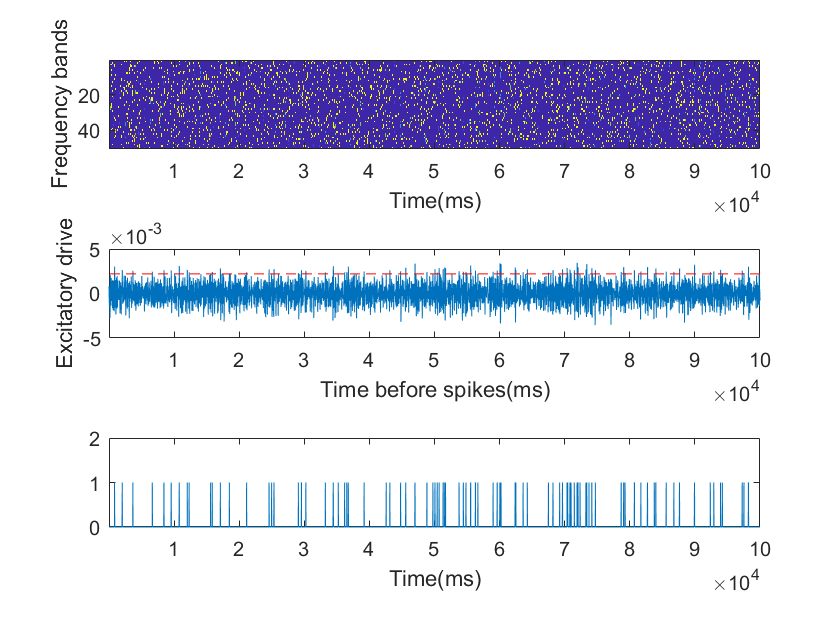

stimulus100 = Stimulus(:,500:100500); %Take the stimulus between .5 and 100.5 seconds
excitdriv100 = excitdrive(:,500:100500); %Take the excitatory drive of the neuron
                                         %between .5 and 100.5 seconds
newspiker = spiker(:,500:100500); %Takes the matrix of spikes between .5 and 100.5 seconds
ax = [];
subplot(3,1,1);
imagesc(stimulus100); %Plots the stimulus
xlabel('Time(ms)');
ylabel('Frequency bands');
subplot(3,1,2);
plot(excitdriv100); %Plots the excitatory drive
hline = refline([0 .0022]); %Create a line of 0 slope at .0022 (threshold)
hline.Color = 'r';
hline.LineStyle = '--';
xlabel('Time before spikes(ms)');
ylabel('Excitatory drive');
xlim([1 100000]);
subplot(3,1,3);
plot(newspiker); %Plots the spikes
xlabel('Time(ms)');
xlim([1 100000]);
ylim([0 2]); 

5. So now we are going to generate the spike-train average preceding each spike. The idea is that we can isolate the 150 ms before each spike, then calculate the average amplitude at each wavelength for all 150 ms across the various spikes. 

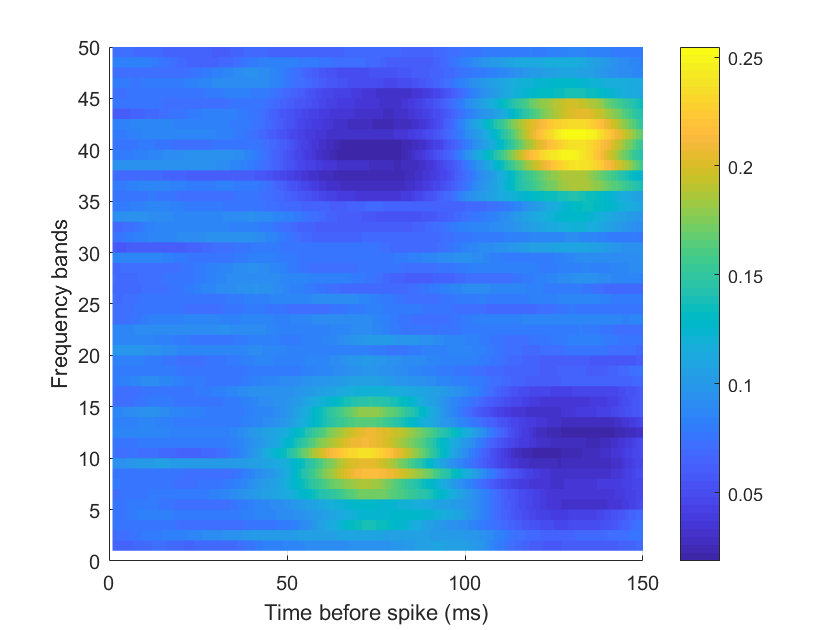

STA = zeros(50, 150); %Our STA will only be 150 ms long, across the 50 frequency bands
[na, numberofspikes] = size(spiketimes); %We need the number of spikes to iterate over
for k = 1:numberofspikes
    spikepoint = spiketimes(1,k); %Go through each spike time
    beginningpoint = spikepoint-150; %Start 150 ms before the spike
    endingpoint = spikepoint-1; %End at the spike itself
    STAcurrent = Stimulus(:,beginningpoint:endingpoint); %Take the stimulus values 150 ms before the spike
    STA = STA + STAcurrent; %Add the stimulus values 150 ms before each spike
end
STA = STA/numberofspikes; %Average the stimulus values 150 ms before each spike
subplot(1,1,1)
surf(1:150,1:50,STA,'edgecolor','none'); %Create a surface plot of the STA
view(0,90);
xlabel('Time before spike (ms)');
ylabel('Frequency bands');
colorbar;

We can see that the STA resembles the original STRF kernel, which is logical. The STA sounds like a low pitch sound quickly changing to a higher pitched sound.

6. In the first part of the STA, we see that there is no definitive signal, either of very high or of very low amplitude, which would be triggering the neuron (the amplitude is middle of the range, and non-specific). This is because our receptive field only covers 100 ms - any information outside of those prior 100 ms (before 100 ms) is irrelevant to the neuronal firing, thus the average of the stimuli across many spike-preceding-times (the time before a spike) comes close to the average amplitude.

7. The STA seems to have recovered the neuron's receptive field quite well - the receptive field very much resembles the original kernel. It doesn't seem to have the same "resolution" as the original kernel - there is more noise (literally but also as in signal-to-noise) between the different "spots" on the STA compared to the STRF kernel that we started with. This is likely because we are taking the average of many spikes-triggering sequences, and that these sequences include the baseline firing rate of the neuron without any input signal. We have not accounted for this baseline firing rate and thus our STA will be have more variation than the original, more idealistic, STRF. We could potentially account for this baseline firing rate by measuring the firing without any noise and subtract this from the STA that we have.